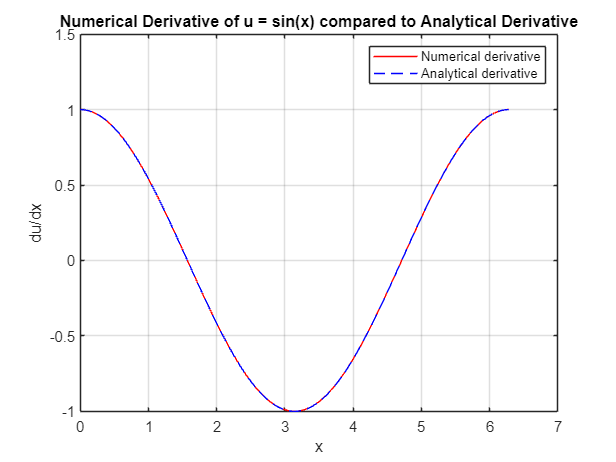

clc;

clear;

% Define the interval and grid spacing
x = linspace(0, 2*pi, 100);
h = x(2) - x(1);

% Evaluate the sine function over this interval
u = sin(x);

% Call the function to calculate the derivative
du_dx = calculateDerivative(u, h);

% Plot the numerical derivative and analytical derivative
figure;
plot(x, du_dx, 'r-', x, cos(x), 'b--');
xlabel('x');
ylabel('du/dx');
title('Numerical Derivative of u = sin(x) compared to Analytical Derivative');
legend('Numerical derivative', 'Analytical derivative');
grid on;

function du_dx = calculateDerivative(u, h)
    % Function to calculate the derivative of a given vector u using spacing h
    % using different finite difference schemes for the boundaries and interior points.
    
    % Initialize the derivative vector
    du_dx = zeros(size(u));
    n = length(u);
    
    % Three-point forward difference at the first point
    du_dx(1) = (-3*u(1) + 4*u(2) - u(3)) / (2*h);
    
    % Second-order central difference for intermediate points
    for i = 2:n-1
        du_dx(i) = (u(i+1) - u(i-1)) / (2*h);
    end
    
    % Three-point backward difference at the last point
    du_dx(end) = (3*u(end) - 4*u(end-1) + u(end-2)) / (2*h);
    
    % The function now simply returns the derivative vector
end
